cellstruct = dat.stat;
stat = FStats(dat);
cells=1:size(stat.dF,2);
pos_xy = zeros(numel(cells),2);

for i=1:numel(cellstruct)
    pos_xy(i,:) = cellstruct(i).med;
end

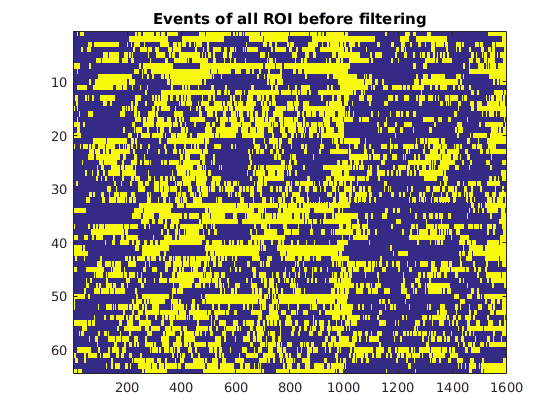

imagesc(stat.peak_extends);
title('Events of all ROI before filtering');

Fluorescence trace for the ROI

% dF = stat.dF;
% ps_filename = ['trace_' dat.finfo.filename '.ps'];
% for i=1:min(size(dF,1),30)
%     is_kept = sum(stat.keep_cells==i) > 0;
%     plot(Fcell(i,:),'color','b');
%     hold on;
%     plot(FcellNeu(i,:),'color','r');
%     hold off;
%     legend('ROI Fluorescence', 'Neuropil Fluorescence');
%     title(sprintf('Fluorescence for ROI %d, kept=%d', i, is_kept));
%     print(ps_filename, '-dpsc', '-append');
%     
%     plotTrace(dF(i,:), 0, peaks{i});
%     title(sprintf('Trace for ROI %d', i));
%     print(ps_filename, '-dpsc', '-append');
% end


Only analyse the selected cells

filtered_stat = filterFstat(stat);
keep_cells = filtered_stat.keep_cells;
dF = filtered_stat.dF;
peaks = filtered_stat.peaks;
ncells = size(dF,1);

event_bins = filtered_stat.peak_extends;
event_counts = filtered_stat.event_counts;

pos_xy = pos_xy(filtered_stat.keep_cells,:);
stats = cellstruct(keep_cells);

[B, I] = sort(event_counts, 'descend');

Calculate distance between cells measured in pixels

pos_x = repmat(pos_xy(:,1), 1, ncells);
pos_y = repmat(pos_xy(:,2), 1, ncells);

distance = sqrt((pos_x' - pos_x) .^2 + (pos_y' - pos_y) .^2) ;


Correlations and Custering

CORRS = corr(dF', 'type', 'Kendall');

cluster_count = 3;%ceil(ncells / 8);
cluster_colours = hsv(cluster_count);
[cluster_index, centroid, ~, ~] = kmeans(dF, cluster_count, 'Distance', 'correlation');

Undefined function or variable 'dF1'.

[C,I] = sort(cluster_index);
imagesc(CORRS(I,I));

Correlations between cells depending on their distance

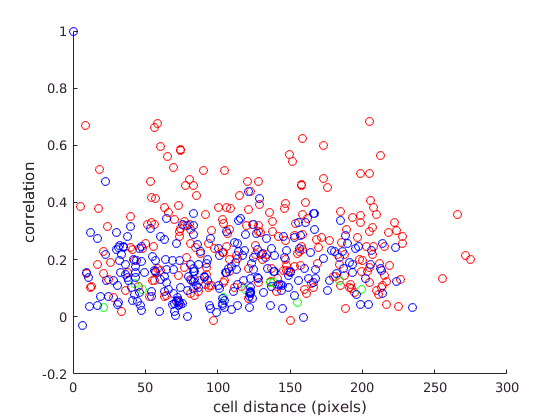

for i=1:cluster_count
    fc = find(cluster_index==i);
    d = distance(fc,fc);
    c = CORRS(fc,fc);
    scatter(d(:), c(:), [], cluster_colours(i,:));
    hold on;
end
hold off;
xlabel('cell distance (pixels)');
ylabel('correlation');

Cluster cells by shape/size? and look for correlations within them

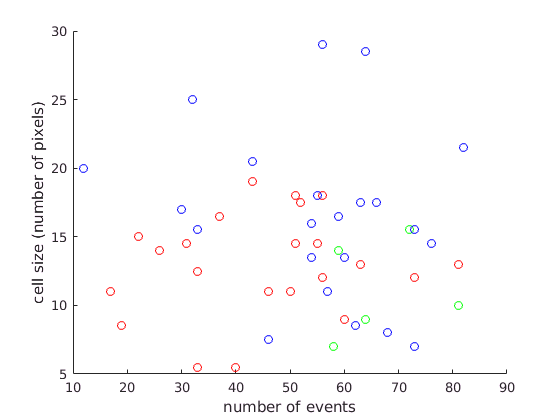

npix = [stats.npix];
for i=1:cluster_count
    fc = find(cluster_index==i);
    scatter(event_counts(fc), npix(fc), [], cluster_colours(i,:));
    hold on;
end
hold off;
xlabel('number of events');
ylabel('cell size (number of pixels)');

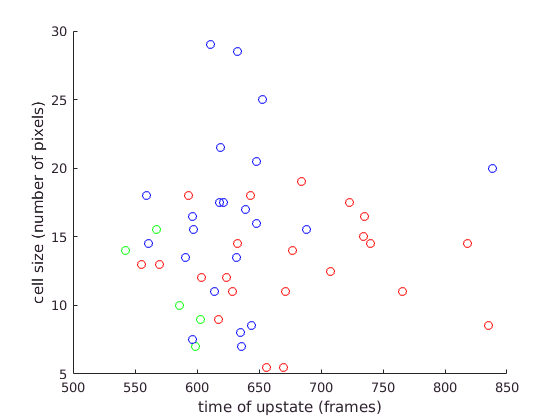

event_durations = sum(event_bins,2);
for i=1:cluster_count
    fc = find(cluster_index==i);
    scatter(event_durations(fc), npix(fc), [], cluster_colours(i,:));
    hold on;
end
hold off;
xlabel('time of upstate (frames)');
ylabel('cell size (number of pixels)');

Distribution of events by amplitude and raising rate

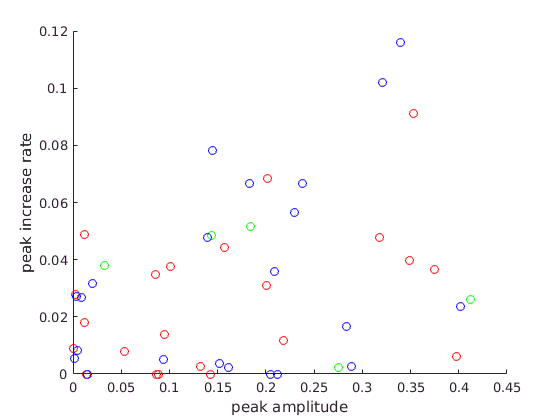

peaks_mat = cell2mat(peaks);
peaks_amp = [peaks_mat.amplitude];
peaks_increase = [peaks_mat.increase_rate];
for i=1:cluster_count
    fc = find(cluster_index==i);
    scatter(peaks_amp(fc), peaks_increase(fc), [], cluster_colours(i,:));
    hold on;
end
hold off;
xlabel('peak amplitude');
ylabel('peak increase rate');

Mean interspike interval

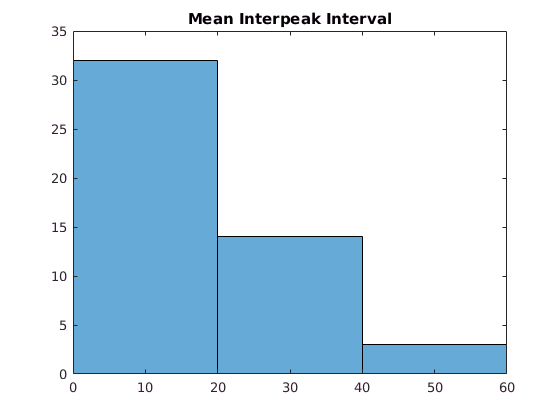

interpeak_interval_mean = zeros(ncells,1);
interpeak_interval_std = zeros(ncells,1);
ipi = [];
for i=1:ncells
    end_indecies = [peaks{i}.end_index];
    start_indecies = [peaks{i}.start_index];
    intervals = bsxfun(@minus,...
                       start_indecies(2:end),...
                       end_indecies(1:end-1));
    ipi = [ipi intervals];
    interpeak_interval_mean(i) = mean(intervals);
    interpeak_interval_std(i) = std(intervals);
end

histogram(interpeak_interval_mean, 'BinWidth', 20);
title('Mean Interpeak Interval');

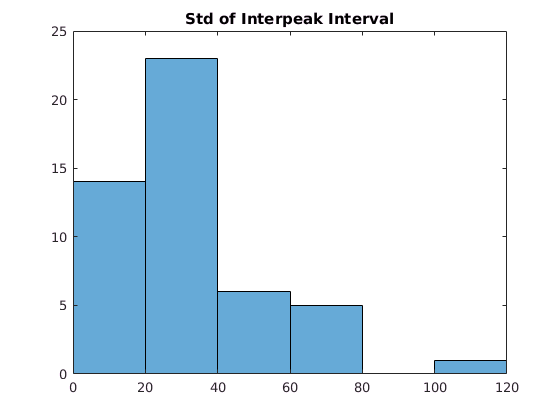


histogram(interpeak_interval_std, 'BinWidth', 20);
title('Std of Interpeak Interval');

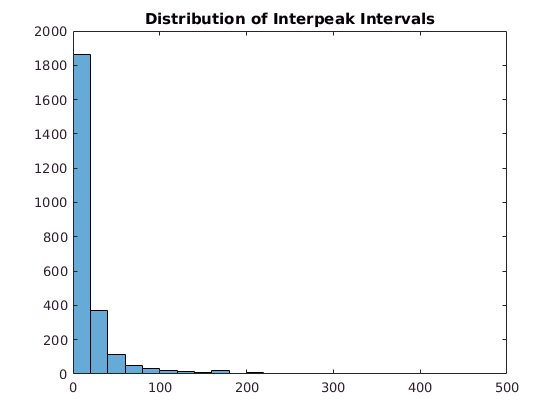


histogram(ipi, 'BinWidth', 20);
title('Distribution of Interpeak Intervals');

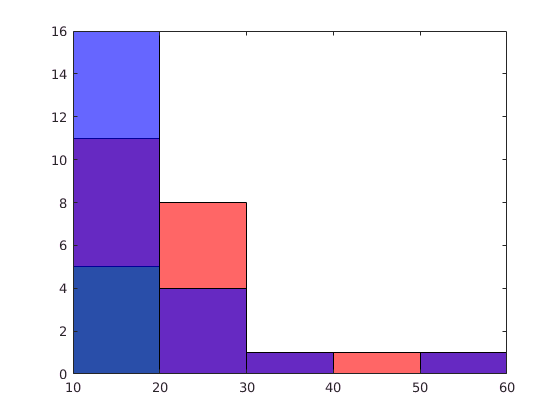


for i=1:cluster_count
    fc = find(cluster_index == i);
    histogram(interpeak_interval_mean(fc),...
        'BinWidth', 10,...
        'FaceColor', cluster_colours(i,:));
    hold on;
end
hold off;

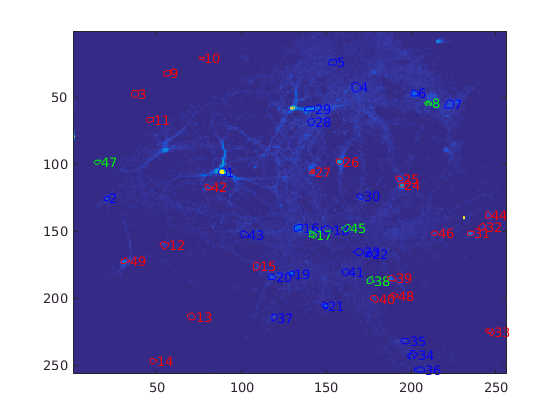

figure;
imagesc(dat.mimg);
%colormap(gray);

hold on;

% draw each ROI
for i=1:numel(keep_cells)
        x = stats(i).xpix;
        y = stats(i).ypix;
        bw = boundary(x,y);
        
        cluster_i = cluster_index(i);
        cluster_colour = cluster_colours(cluster_i,:);
        plot(x(bw), y(bw), 'Color', cluster_colour);
        text(max(x), mean(y), ...
            num2str(i),...
            'Color', cluster_colour);
end
hold off;

Cross correlations

[xcorrs, lag]= xcorr(dF', 50);
[M, I] = max(xcorrs,[],1);
max_lag = reshape(lag(I), [ncells ncells]);
max_acor = reshape(M, [ncells ncells]);

auto correlations to see intrinsic rhythym of the cells - max lag after 340 frames

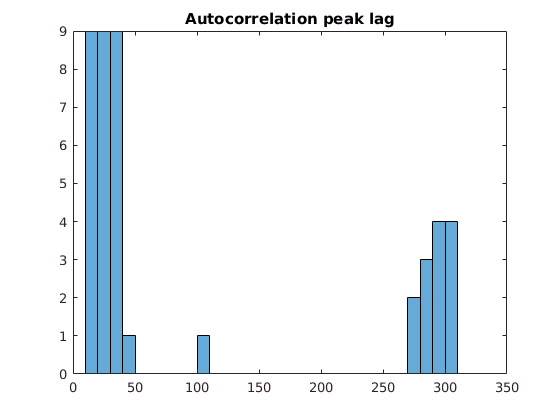

[peak_alags, acorr_peak_vals, ACORRS, lag] = autocorrs(dF);
histogram(peak_alags, 'BinWidth', 10);
title('Autocorrelation peak lag')

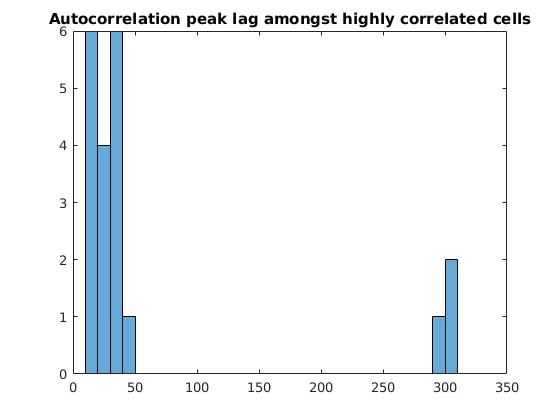


[acorr_peak_vals_sorted,~] = sort(acorr_peak_vals, 'descend');
min_peak_acorr_val = acorr_peak_vals_sorted(floor(length(acorr_peak_vals)/2));
histogram(peak_alags(acorr_peak_vals > min_peak_acorr_val), 'BinWidth', 10);
title('Autocorrelation peak lag amongst highly autocorrelated cells')

Clustering using lags - how to avoid clustering of cells which don't have high strength of correlation?

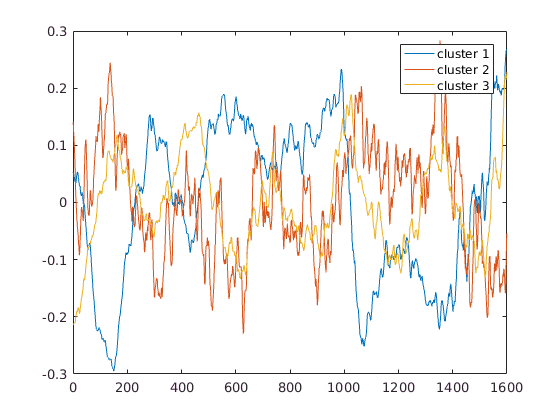

%[lag_cluster,b,sum_dist]=kmeans(max_lag,cluster_count);

legend_info = cell(cluster_count,1);
figure;
for i=1:cluster_count
    fc=find(cluster_index==i);
    y = mean(dF(fc,:), 1);
    plot(exp_smooth(y, 0.15));
    legend_info{i} = ['cluster ' num2str(i)];
    hold on;
end
legend(legend_info);
hold off;

AutoCorrelations within clusters

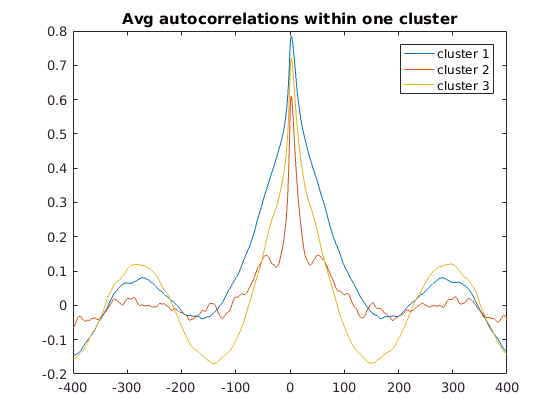

for i=1:cluster_count
    fc = find(cluster_index==i);
    avg_acorr = mean(ACORRS(fc,:), 1);
    plot(lag, exp_smooth(avg_acorr, 0.15));
    hold on;
end

legend(legend_info);
title('Avg autocorrelations within one cluster')
hold off;

[coeff,score,latent,tsquared,explained,~] = pca(exp_smooth(dF, 0.2));
nprinciplas = find(cumsum(explained) >=60, 1);
pcaF = coeff(:,1:nprinciplas)';

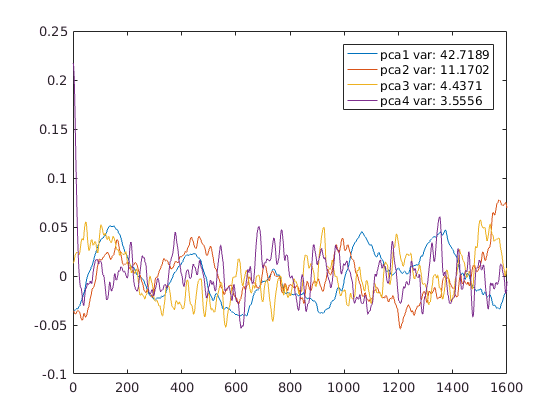

for i=1:nprinciplas
    plot(exp_smooth(pcaF(i,:), 0.2), ...
        'DisplayName', ['pca' num2str(i) ' var: ' num2str(explained(i))]);
    hold on;
end
hold off;
legend('show');

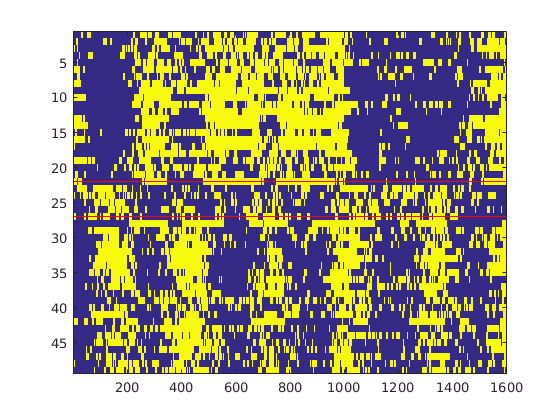

[C,I] = sort(cluster_index);
imagesc(event_bins(I,:));
hold on;
for i=1:cluster_count
    val = find(C == i,1) - 1;
    plot([1 size(dF,2)], [val val], 'color', 'r');
end
hold off;

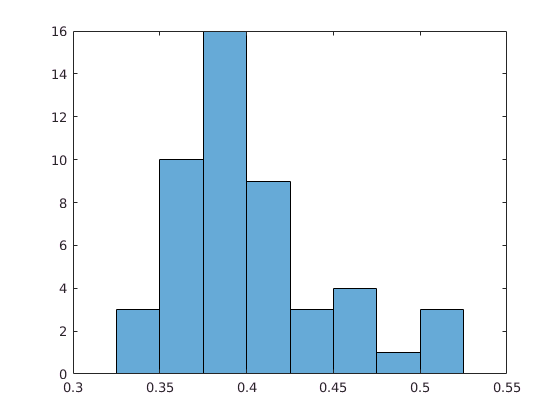

histogram(mean(event_bins, 2),'BinWidth',0.025)

TODO:

event correlation

event sequence between cells? or synchronicity in the network